#  LESSON 08/01/2026

clear; clf; clc;

## Parameters

p.L = 0.23e-3;      %[V/A*sec]
p.cm = 23.4e-3;     %[Nm/A]
p.R = 2.4;          %[Ohm]
p.J = 0.23e-6;      %[N*m^2]
p.D = 0.4191e-5;    %[Nm/rad*sec]

p.t0 = 0;           %[s] start simulation time
p.tend = 0.01;      %[s] stop simulation time

pid.kp = 1;         % proportional action pid controller
pid.ki = 0;         % Integral action pid controller
pid.kd = 0;         % derivative action pid controller

## a) Open loop simulation of the motor

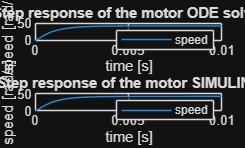

p.u = 1;    %step response to 1V power supply

[t,y] = ode45(@motorDgl,[p.t0,p.tend],[0,0],[],p);      %ODE solver
outOpenLoop = sim('exercise4_SIM');                     %SIMULINK simulation

figure()
subplot(2,1,1)      
plot(t,y(:,2))      % Plot of the simulation made with ODE solver
title("Step response of the motor ODE solver");
legend("speed")
grid on; xlabel("time [s]"); ylabel("speed [rad/s]");

subplot(2,1,2)      % Plot of the simulation made with simulink simulation
plot(outOpenLoop.openLoop.time,outOpenLoop.openLoop.signals(2).values)
title("Step response of the motor SIMULINK");
legend("speed")
grid on; xlabel("time [s]"); ylabel("speed [rad/s]");

## b) improve control 

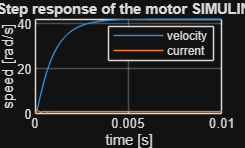

figure()
plot(outOpenLoop.openLoop.time,outOpenLoop.openLoop.signals(2).values,...
    outOpenLoop.closeLoop.time,outOpenLoop.closeLoop.signals(2).values)
title("Step response of the motor SIMULINK");
legend("velocity","current")
grid on; xlabel("time [s]"); ylabel("speed [rad/s]");

## c) different solver test

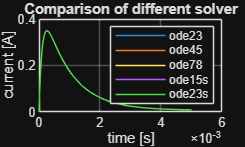

% Solving with different ode solver
[t1,y1] = ode23(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t2,y2] = ode45(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t3,y3] = ode78(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t4,y4] = ode15s(@motorDgl,[p.t0,0.005],[0,0],[],p);
[t5,y5] = ode23s(@motorDgl,[p.t0,0.005],[0,0],[],p);

figure()
plot(t1,y1(:,1),t2,y2(:,1),t3,y3(:,1),t4,y4(:,1),t5,y5(:,1));   % Plot all the results
title("Comparison of different solver")
legend("ode23","ode45","ode78","ode15s","ode23s");
grid on; xlabel("time [s]"); ylabel("current [A]");

## Differential equation

function dz = motorDgl(t,z,p)
    i = z(1);
    w = z(2);

    di = 1/p.L * (p.u - i*p.R - p.cm*w);
    dw = 1/p.J * (i*p.cm - w*p.D);

    dz = [di; dw];  % Return the derivatives as a column vector
end
